**System Control Example : PID Controller**

**Controller configuration with cruise system**

**Cruise model transfer function (velocity control)**


$$P\left(s\right)=\frac{V\left(s\right)}{U\left(s\right)}=\frac{1}{\mathrm{ms}+b}$$


**PID controller**


$$C\left(s\right)=K_p +\frac{K_i }{s}+K_d s=\frac{\left(K_d s^2 +K_p s+K_i \right)}{s}$$


**Controller performance specification**

- **Rise time < 5s**

- **%OS < 10%**

- **Steady-state error < 2%**

**Cruise system model setup**

m = 1000; b = 50;

s=tf('s');
P_cruise = 1/(m*s+b); %플랜트
t_cruise = 0:0.1:30; %시간
r_cruise = 10; %입력

**System selection**

t_system = t_cruise;
P_system = P_cruise;
r_system = r_cruise;

**P control**

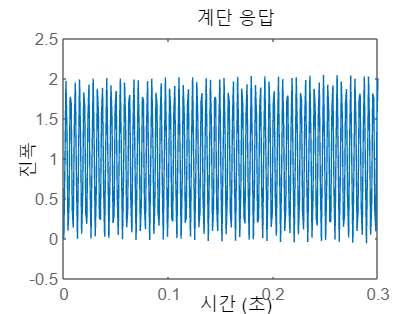

Kp = 1000;
C = Kp;
sys_cl = feedback(C*P_system,1); % C -> P 피드백
figure(1)
step(r_system*sys_cl,t_system)


%gain을 키우면 정상상태오차는 감소, 과도응답은 커지게 됨
% 크루즈 시스템은 1차시스템이라 과도응답,오버슈트 발생안함

**Disturbance  **

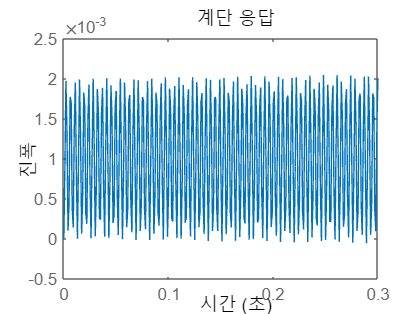

Kp=1000;
C= Kp;

dist_cl = feedback(P_system,C);
figure(2)
step(dist_cl,t_system)

%외란의 영향도 Gain을 키우면 감소한다.

**PI control**

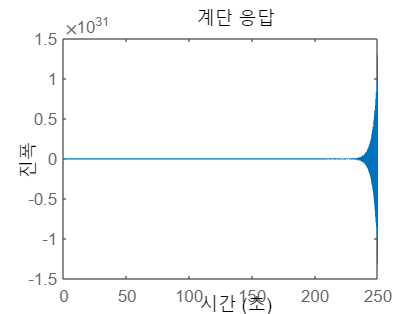

Kp=1000;
Ki=200;
C=Kp+Ki/s;
sys_cl=feedback(C*P_system,1);
figure(3)
step(r_system*sys_cl);


%Ki는 정상상태오차를 줄여주고 반응시간을 빠르게 해줌
%그러나 오버슈트가 발생

**Disturbance**

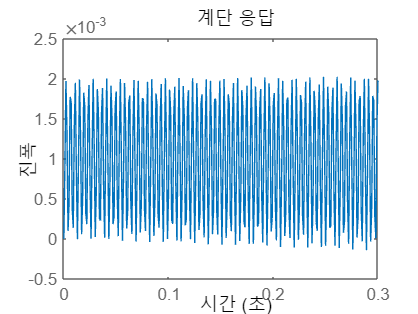

dist_cl=feedback(P_system,C);
step(dist_cl,t_system)


%외란의 영향도 Ki에 의해 감소 

**PID control**

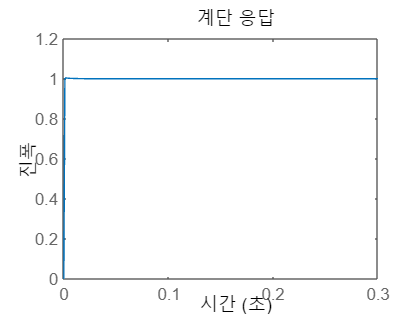

Kp = 1000;
Ki = 150;
Kd = 10;

C = Kp+Ki/s+Kd*s;
sys_cl=feedback(C*P_system,1);
step(r_system*sys_cl,t_system)


stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 1.0061e-04
    TransientTime: 1.7368e-04
     SettlingTime: 1.7368e-04
      SettlingMin: 0.9027
      SettlingMax: 1.0039
        Overshoot: 0.3894
       Undershoot: 0
             Peak: 1.0039
         PeakTime: 3.4159e-04


**Motor system**

- Settling time <0.04s

- %OS <10%

- Steady-state error ~ 0

J =3.2284E-6; b = 3.5077E-6; K = 0.0274; L = 2.75E-6; R=4;
s=tf('s');
t_motor=0:0.001:0.3

t_motor =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


r_motor = 1;
P_motor = K/(s*((J*s+b)*(L*s+R)+K^2));

t_system = t_motor;
r_system = r_motor;
P_system = P_motor;

**P control**

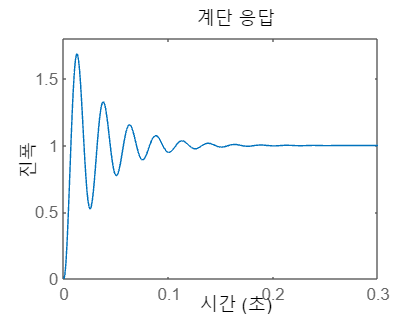

Kp=30;
C=Kp;

sys_cl = feedback(C*P_system,1);
step(r_system*sys_cl,t_system);

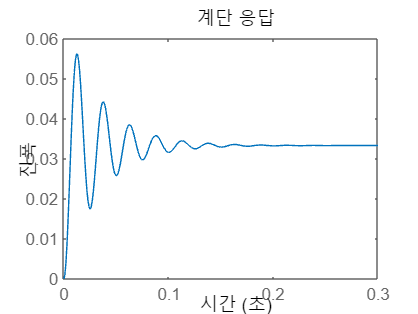

dist_cl=feedback(P_system,C);
step(dist_cl,t_system)

**PI control  -> 외란 제거 가능**

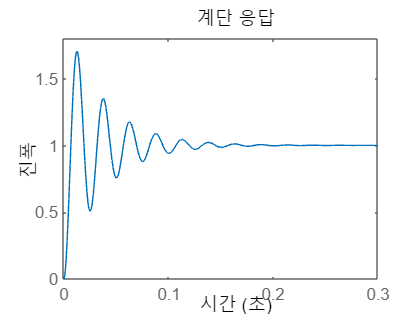

Kp=30;
Ki=100;
C=Kp+Ki/s;

sys_cl = feedback(C*P_system,1);
step(r_system*sys_cl,t_system);

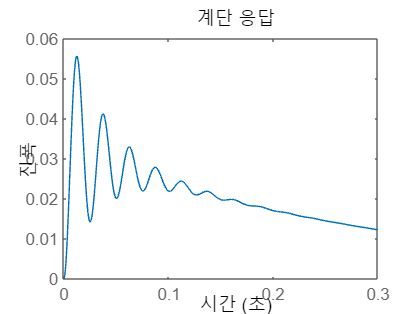

dist_cl=feedback(P_system,C);
step(dist_cl,t_system)

**PID control -> 과도응답 반응 좋아짐**

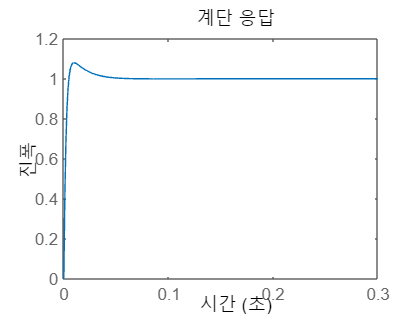

Kp=30;
Ki=1000;
Kd= 0.25;
C=Kp+Ki/s+Kd*s;

sys_cl = feedback(C*P_system,1);
step(r_system*sys_cl,t_system);

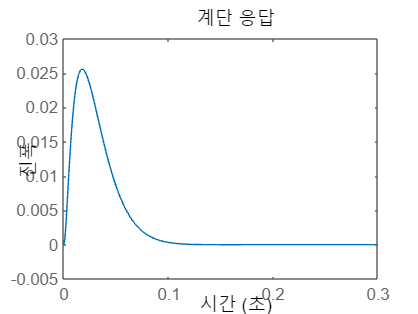

dist_cl=feedback(P_system,C);
step(dist_cl,t_system)


stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.0032
    TransientTime: 0.0316
     SettlingTime: 0.0316
      SettlingMin: 0.9142
      SettlingMax: 1.0802
        Overshoot: 8.0168
       Undershoot: 0
             Peak: 1.0802
         PeakTime: 0.0098


**PID Tuner**

pidTuner(P_system,'pid')